input_path = fullfile("D:/2021-01-17-Hailing-Ileum/output/max/");
input_dim = [3072 3072 45 4];


data_dirs = dir(fullfile(input_path, "Position*"));
data_dirs = struct2table(data_dirs);
data_dirs = natsort(data_dirs.name);

Ndirs = numel(data_dirs);


current_section = "section8"

current_section = "section8"

position_range = [73:84];
position_dirs = {};
for i=position_range
    position_dirs{end+1} = sprintf("Position%03d", i);
end
rotation_degress = -180; 

% merge dots 
stitch_file = fullfile(input_path, "dapi_rotated", current_section, "TileConfiguration.registered.txt");
%% Setup the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 6);

% Specify range and delimiter
opts.DataLines = [5, Inf];
opts.Delimiter = ["(", ")", ",", ";"];

% Specify column names and types
opts.VariableNames = ["Definetheimagecoordinates", "Var2", "Var3", "VarName4", "VarName5", "VarName6"];
opts.SelectedVariableNames = ["Definetheimagecoordinates", "VarName4", "VarName5", "VarName6"];
opts.VariableTypes = ["double", "string", "string", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
opts.ConsecutiveDelimitersRule = "join";

% Specify variable properties
opts = setvaropts(opts, ["Var2", "Var3"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Var2", "Var3"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "Definetheimagecoordinates", "TrimNonNumeric", true);
opts = setvaropts(opts, "Definetheimagecoordinates", "ThousandsSeparator", ",");

% Import the data
TileConfiguration = readtable(stitch_file, opts);
TileConfiguration.Properties.VariableNames = {'tile' 'x' 'y' 'z'};
TileConfiguration.x = int16(TileConfiguration.x);
TileConfiguration.y = int16(TileConfiguration.y);
%TileConfiguration = TileConfiguration(ismember(TileConfiguration.tile, position_range), :);

% section 5 
% TileConfiguration.tile = [41, 48, 54, 42, 47, 55, 43, 46, 56, 44, 45, 57]';

head(TileConfiguration, 5)

ans = 5×4 table
    tile     x       y      z
    ____    ____    ____    _

     73        0       0    0
     74     2785      38    0
     75     5542      75    0
     76     8341     108    0
     80      -38    2790    0



%% Clear temporary variables
clear opts

## modify each tile

trim_range = 1:40;
global_offsets = int32(abs([min(TileConfiguration.x); min(TileConfiguration.y)]));

% load stitched dapi image
dapi_file = fullfile(input_path, "stitched_images", current_section, 'dapi.tif')

dapi_file = "D:\2021-01-17-Hailing-Ileum\output\max\stitched_images\section8\dapi.tif"

dapi_img = imread_big(dapi_file);
dapi_max = max(dapi_img, [], 3);


merged_points = int32([]);
merged_reads = {};
merged_region = [];

for r=1:size(TileConfiguration,1)
    
    % get each row of tileconfig
    curr_row = table2cell(TileConfiguration(r, :));
    [tile, x, y, z] = curr_row{:};
    
    % load dots of each tile
    curr_position_dir = sprintf("Position%03d", tile)
    curr_dot_file = fullfile(input_path, curr_position_dir, "goodPoints_max3d_bk.mat");
    load(curr_dot_file);
    
     if rotation_degress == -90
        % rotate 90 c
        temp = goodSpots;
        goodSpots(:, 2) = temp(:, 1);
        goodSpots(:, 1) = 3073 - temp(:, 2);
    elseif rotation_degress == -180
        % rotate 180 c
        temp = goodSpots;
        goodSpots(:, 1) = 3073 - temp(:, 1);
        goodSpots(:, 2) = 3073 - temp(:, 2);
    end
    
    % trim along z
    toKeep = ismember(goodSpots(:,3), trim_range);
    goodSpots = goodSpots(toKeep, :);
    goodReads = goodReads(toKeep);
    
    % add offset
    goodSpots = int32(goodSpots) + int32([x y z]);
    goodSpots(:, 1) = goodSpots(:, 1) + global_offsets(1); 
    goodSpots(:, 2) = goodSpots(:, 2) + global_offsets(2); 
        
    % construct dots region
    current_min = min(goodSpots, [], 1);
    current_max = max(goodSpots, [], 1);
    current_region = zeros(size(dapi_max));
    current_region(current_min(2):current_max(2), current_min(1):current_max(1)) = 1;
    
    % merge dots 
    if ismember(tile, position_range)
        if isempty(merged_region)
            merged_region = current_region;
        else
            current_overlap = merged_region & current_region;
            merged_region = merged_region | current_region;
            current_region = current_region - current_overlap; 
            
            temp_cell = num2cell(goodSpots, 2); 
            current_lindex = cellfun(@(x) sub2ind(size(dapi_img), x(2), x(1)), temp_cell);
            current_logical = logical(current_region(current_lindex));
            goodSpots = goodSpots(current_logical, :);
            goodReads = goodReads(current_logical);
        end
        
        % save current 
        merged_points = [merged_points; goodSpots];
        merged_reads = [merged_reads; goodReads];
    end
end

curr_position_dir = "Position073"

curr_position_dir = "Position074"

curr_position_dir = "Position075"

curr_position_dir = "Position076"

curr_position_dir = "Position080"

curr_position_dir = "Position079"

curr_position_dir = "Position078"

curr_position_dir = "Position077"

curr_position_dir = "Position081"

curr_position_dir = "Position082"

curr_position_dir = "Position083"

curr_position_dir = "Position084"

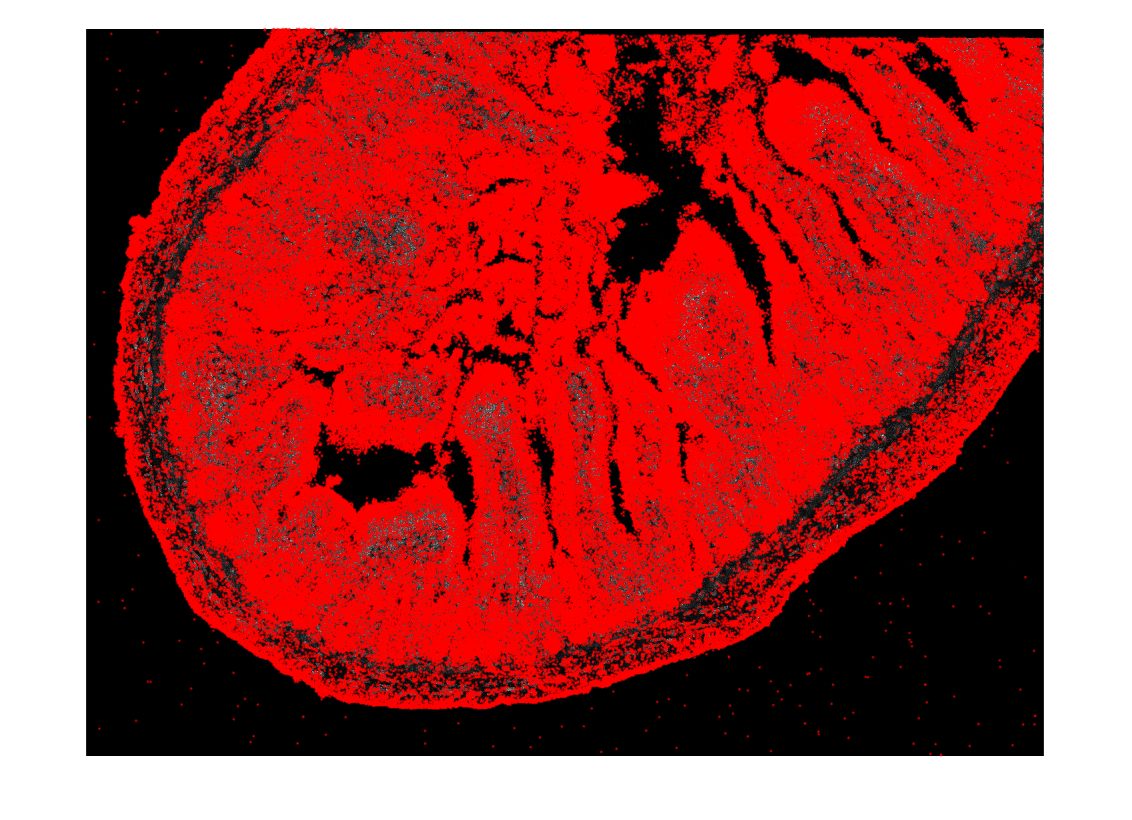


plot_centroids(merged_points, dapi_max, 4)

save(fullfile(input_path, 'merged_goodPoints_max3d', sprintf("%s.mat", current_section)), "merged_points", "merged_reads");